%%% READ ME %%%
% Scriptet virker kun på Matlab 2020 og nyere
% Legg ActualSpeedrun mappen i C:\Users\Username\Documents\MATLAB
% VIEW -> HIDE CODE (for beste visning

addpath('ActualSpeedrun/Funksjoner/') % Legger til folder med funksjoner til matlab path
addpath('ActualSpeedrun/Images') % Legger til folder med bilder i matlab path

%Initialisering
format short
sympref('PolynomialDisplayStyle','ascend'); % Viser polyniomialer med laveste order til venstre
clearvars
cla
clf

`VIEW -> HIDE CODE `(for beste visning)

# Taylor Expansion for Dummies

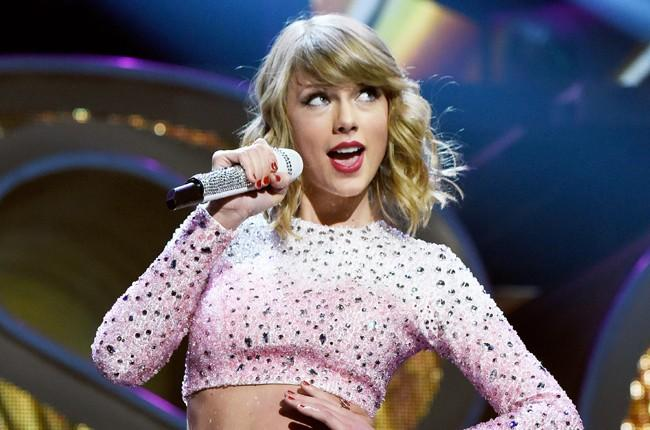

*"It's expansion time!" - Taylor Swift 2020*

**Evaluer taylor *****p(x)***** for funksjon***** y(x)***** rundt punkt *****x = a***

Sett *a = 0* for MacLaurin

syms x yInput
o = 1; %Initialiserer order
yInput = sqrt(x+1);
a = 0;
o = 4;
o = o+1;
 

yInput

$$yInput = \sqrt{1+x}$$


yInput = symfun(yInput,x) %convert y to symfun

$$yInput(x) = \sqrt{1+x}$$


Taylor = taylor(yInput,x,'ExpansionPoint', a, 'order', o); % taylor av y med hensyn til x, rundt punkt a, for order o
Taylor = symfun(Taylor, x); % convert taylor from sym to symfun
display(Taylor)

$$Taylor(x) = 1+\frac{x}{2}-\frac{x^{2}}{8}+\frac{x^{3}}{16}-\frac{5\,x^{4}}{128}$$

%Viser simplified Taylor om den er ulik fra vanlig taylor
simplifiedTaylor = simplify(Taylor);
if simplifiedTaylor ~= Taylor
display(simplifiedTaylor)
end

% Finner udefinerte verdier for x
[n,d] = numden(yInput); %Finner nevnere for y(x)
illegalEqn = d==0; % Illegal equation
illegalValue = solve(illegalEqn,x); % Finner udefinerte verdier for y(x)
if isempty(illegalValue) ~= 1 %Hvis udefinerte verdier er funnet så kjør
 illegalValue = string(illegalValue);
 disp('y(x) har udefinerte verdier:');
 disp('x = ' + illegalValue);
 
 illegalValue = double(illegalValue);
end

disp(func2link(yInput));

<a href="https://www.wolframalpha.com/input/?i=(x%2B1)%5E(1%2F2)">Vis funksjon i wolfram</a>


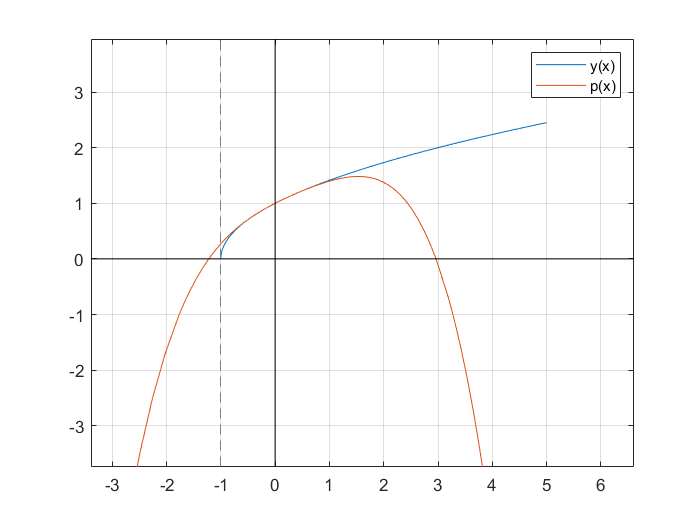

%% PLOT SECTION %%

orderScale = (1/o)+2; % Bestemmer skalar for zoom-level basert på order av taylor

%Akser for grafen
xAxisMin = a-5;
xAxisMax = a+5;
pAxisMin = a-((xAxisMax-a)*orderScale); %taylor grafes med lengde på hver side av a som spesifisert av orderScale
pAxisMax = a+((xAxisMax-a)*orderScale);



A = xAxisMin:xAxisMax;
illegalBurger = ismember(illegalValue,A);
isempty(illegalBurger);
if isempty(illegalBurger)  %Sjekk om array gir deling på 0
    A = yInput(xAxisMin:xAxisMax);
                              % Lager en array med verdier for x mellom xAxisMin og xAxisMax
                              % Brukes kun for å bestemme hvor grafen
                              % 'zoomer' inn. Denne kjører ikke hvis det
                              % finnes 'ulovlige' verdier for x
end



yAxisMax = double(max(A)); %Gir maks akse for y basert på høyeste punkt for y(x)

if yAxisMax == 0 %Hvis makspunktet er 0 trenger utregninga litt ekstra hjelp her�
    yAxisMax = 5;
else
yAxisMax = yAxisMax + abs(yAxisMax*.1); % Skalerer maksaksen til 1 prosent av maksverdi for y(x)
end

yAxisMin = double(min(A));
if yAxisMin == 0
    yAxisMin = -5;
else
yAxisMin = yAxisMin - abs(yAxisMin*.2);    
end

%Plot y(x) og Taylor over hverandre
yPlot = fplot(yInput, [xAxisMin xAxisMax]);  % Plot y(x)
hold on;
pPlot = fplot(Taylor, [pAxisMin pAxisMax]); % Plot taylor
ylim([yAxisMin yAxisMax])
xlim([xAxisMin xAxisMax])
grid on
line ([-100 100], [0 0], 'Color','black','LineWidth', 0.1) % x-akse
line ([0 0], [-100 100], 'Color','black','LineWidth', 0.1) % y-akse
legend ('y(x)','p(x)'); 
hold off

**Estimer verdi av y(x) med taylor og vis differanse**

x = a; % Setter en default verdi for x
x = 0;
 


yEval = eval(yInput);
disp("y(x) = " + yEval)

y(x) = 1


taylorEval = eval(Taylor);
disp("Taylor p(x) = " + taylorEval)

Taylor p(x) = 1


disp("Differanse = " + (yEval - taylorEval))

Differanse = 0


**Estimer bestemt integral på bakgrunn av Taylor**

integralFra = 0; % Initialiserer 
integralTil = 1; % Initialiserer

integralFra = 0;
integralTil = 1;
 

TaylorMatlabFun = matlabFunction(Taylor); % Gjør Taylor om til type function_handle
q = integral(TaylorMatlabFun,integralFra,integralTil) % estimerer integral basert på Taylor

q = 1.2161

**Estimer numerisk uttrykk på bakgrunn av taylor**

syms x pi

estNum = sqrt(0); % Legger inn uttrykk som skal evalueres med taylor
 

displayFormula(["'Uttrykket: '", string(yInput == estNum)]);

$$\mathrm{Uttrykket:}\sqrt{1+x}=0$$

displayFormula(["'Forsøkes løst med: '", string(Taylor == estNum)])

$$\mathrm{Forsøkes løst med:}\frac{x}{2}-\frac{x^{2}}{8}+\frac{x^{3}}{16}-\frac{5\,x^{4}}{128}+1=0$$

x = solve(yInput == estNum,x); % Solver uttrykket basert på estNum med hensyn til x
symEst = subs(Taylor); % substituter symbolsk x med verdien fra estNum
% double(symEst); % double-verdi istedet for eksakt
disp(symEst); % vis eksakt

$$\frac{35}{128}$$

disp(double(symEst)); % vis double 

    0.2734




% To do:
% 
% Error term
% Finne eventuell konvergering



% Resetter settings laget av dette scriptet
sympref('default'); % Change preferences back to normal
